# Descomposición espectral

load("../../Clase Github/Utils4SP/Datasets/S5_Estadistica101_LaVenganza.mat")

## Previsualización

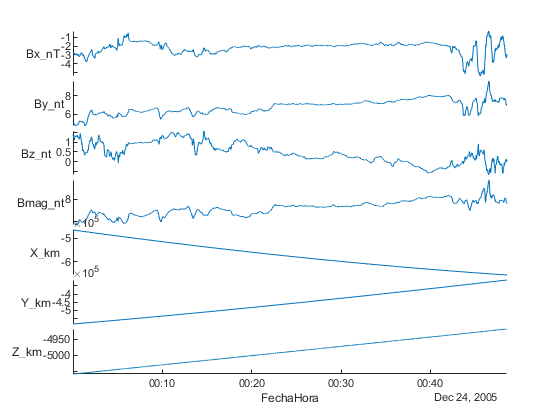

figure
stackedplot(Cassini,"XVariable","FechaHora")

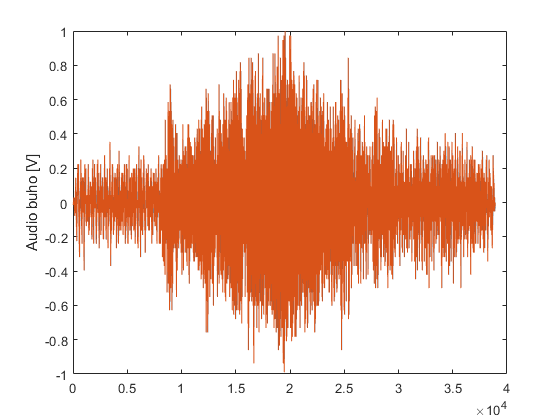

figure
plot(buho)
ylabel("Audio buho [V]")

## FFT

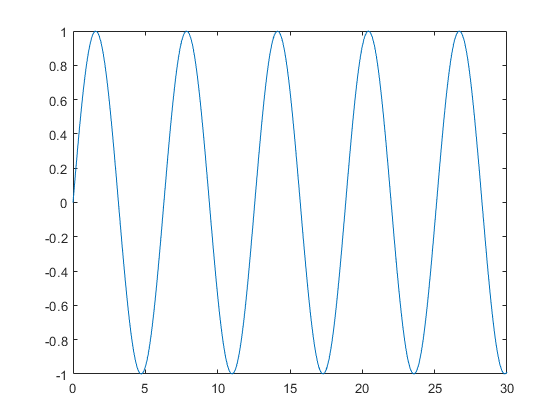

Ts=0.1;
fs=1/Ts;
N=numel(X_1);
t=0:Ts:30;
x=@(t) sin(t);
X_1=x(t);
figure
plot(t,X_1)

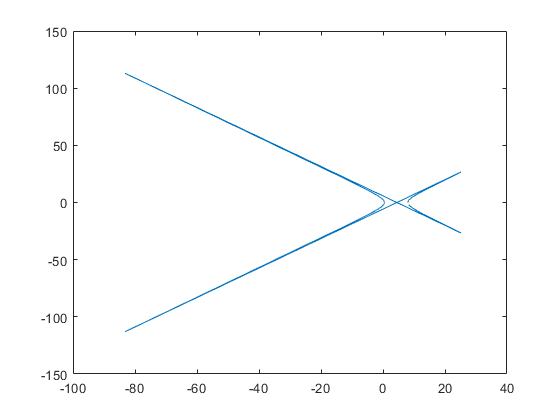

X=fft(X_1);
figure
plot(X)

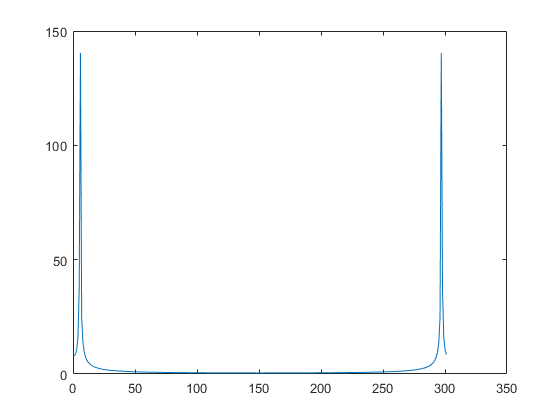

%Graficamos magnitud de X
figure
plot(abs(X))

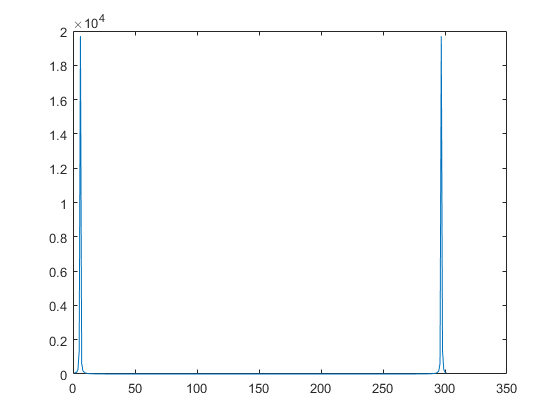

energyDensity=(abs(X)).^2;
figure
plot(energyDensity)

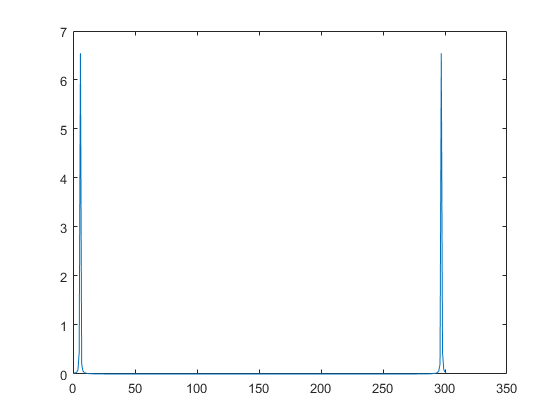

powerDensity=(1/(N*fs))*energyDensity;
figure
plot(powerDensity)

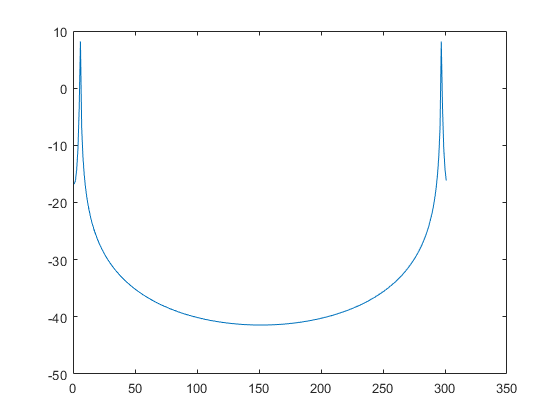

%Lo pasamos a decibeles
powerdB=10*log10(powerDensity);
figure
plot(powerdB)

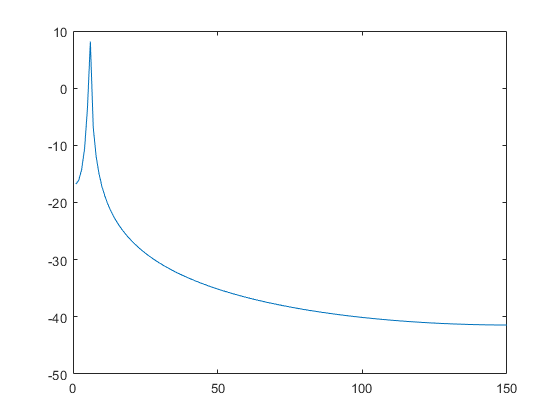

energyDensity_2=energyDensity(1:floor(N/2));
N_energySpectrum=numel(energyDensity_2);
powerDensity_2=energyDensity_2./(N.*fs);
powerdB_2=10*log10(powerDensity_2);
figure
plot(powerdB_2)

## Eje de frecuencias

%Teorema de Nyquist: f_max<fs/2
%Frecuencia de Nyquist
f_Nyquist=fs/2;
%Resolución en frecuencia
%Df=fs/N
Df=fs/N_energySpectrum;
%Nota: fs alta
% + randog dinámico
% + resolución
f=(0:N_energySpectrum-1)./(N_energySpectrum).*f_Nyquist;

## Brillitos para el contenido espectral

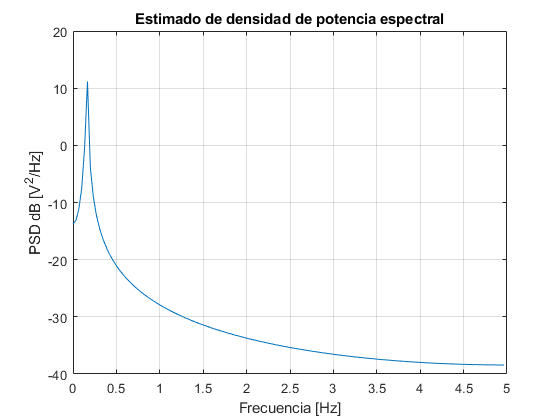

figure
%"pow2db" es una función de Matlab
plot(f,pow2db(2.*powerDensity_2))
title("Estimado de densidad de potencia espectral")
xlabel("Frecuencia [Hz]")
ylabel("PSD dB [V^2/Hz]")
grid on

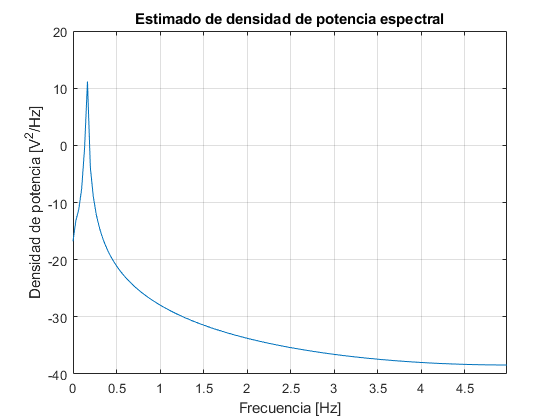

figure
periodogram(X_1,[],N,fs)
ylabel("Densidad de potencia [V^2/Hz]")
xlabel("Frecuencia [Hz]")
title("Estimado de densidad de potencia espectral")

## Periodogram para el buho

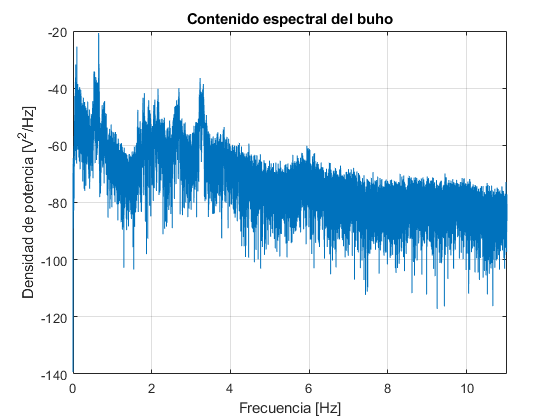

N_buho=numel(buho_left);
figure
periodogram(buho_left,[],N_buho,fs_buho)
ylabel("Densidad de potencia [V^2/Hz]")
xlabel("Frecuencia [Hz]")
title("Contenido espectral del buho")

## Sacar datos del periodograma

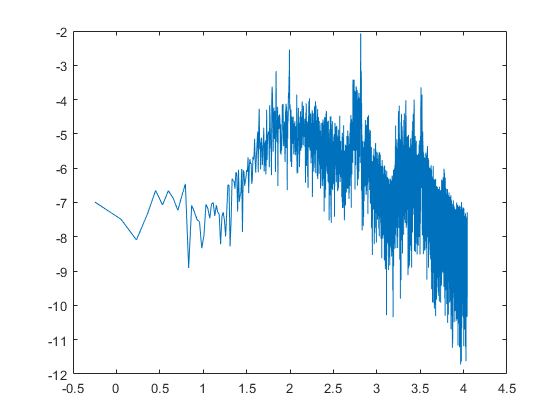

[Pxx,F]=periodogram(buho_left,[],N_buho,fs_buho);
figure
plot(log10(F),log10(Pxx))

## Espectrograma

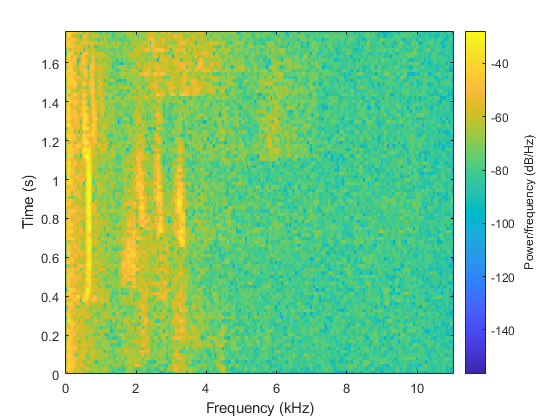

%Cuidado con la RAM
N_spectrogram=round(N_buho/100);
figure
spectrogram(buho_left,N_spectrogram,0,[],fs_buho)